clear variables
load('Tests/RPC_TT_test/e2_TL_RPC/coupled_tl_28par_10std.mat')
[~,d] = size(training_samples);


xi_train = training_samples(1:400,:);
y_train = vouts_train(1:400,:);
f_k = 1:100;
y_test = vouts;


m=1;
tic
[y_predict,n_rpc,d_rpc] = rpc_total(xi_train,y_train(:,f_k),samples,m,'Hermite',0.3,0.01,5e-3);
toc

Elapsed time is 1.291600 seconds.


norm(y_predict-vouts(:,f_k),'fro')/norm(vouts(:,f_k),'fro')

ans = 0.0198

m = 3;
[~,d] = size(xi_train);
N = (m+1)*ones(d,1);
x = TTrand(N,3);
x = TTorthogonalizeLR(x);
x = TTorthogonalizeRL(x);

tic
[y_predict2,N_coefficients,D_coefficients,n_iterations] = rpc_TT(xi_train,y_train(:,f_k),x,samples,m,'Hermite',...
    0.3,0.1,3e-3,0.9,3);

    0.0013    0.0070   56.0000

    0.0013    0.0059   11.0000

    0.0010    0.0058    9.0000

    0.0016    0.0056   19.0000

    0.0011    0.0046   10.0000

    0.0007    0.0045   10.0000

    0.0010    0.0041   16.0000

    0.0017    0.0043   31.0000

    0.0006    0.0032   50.0000

    0.0013    0.0034   37.0000

    0.0003    0.0030   46.0000

    0.0007    0.0030   32.0000

    0.0003    0.0030   21.0000

    0.0006    0.0030   28.0000

    0.0006    0.0030    9.0000

    0.0005    0.0030   11.0000

    0.0009    0.0030    3.0000

    0.0017    0.0029    1.0000

    0.0018    0.0029    2.0000

    0.0013    0.0030    4.0000

    0.0061    0.0066   10.0000

    0.0005    0.0037   37.0000

    0.0005    0.0042   49.0000

    0.0004    0.0041   30.0000

    0.0008    0.0037   20.0000

    0.0005    0.0034   34.0000

    0.0005    0.0031   15.0000

    0.0005    0.0032   28.0000

    0.0005    0.0034   19.0000

    0.0005    0.0032   25.0000

    0.0005    0.0036   38.0000

    0.00

toc

Elapsed time is 144.419459 seconds.


err1 = norm(y_predict2-vouts(:,f_k),'fro')/norm(vouts(:,f_k),'fro')

err1 = 0.0108

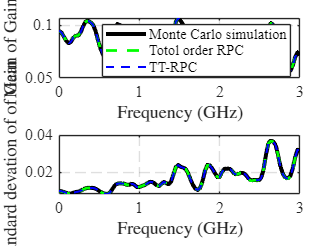

close all

y_mean0 = mean(abs(y_test));
y_sigma0 = std((y_test));

y_mean1 = mean(abs(y_predict));
y_sigma1 = std((y_predict));

y_mean2 = mean(abs(y_predict2));
y_sigma2 = std((y_predict2));

fpoints = linspace(10,3e6,100);
scale = 1e6;
f = figure(1);
subplot(2,1,1);
hold on
plot(fpoints/scale,y_mean0,'k-','LineWidth',3);
plot(fpoints/scale,y_mean1,'g--','LineWidth',2);
plot(fpoints/scale,y_mean2,'b--','LineWidth',1.5);
legend('Monte Carlo simulation','Totol order RPC', 'TT-RPC')
grid on
xlabel('Frequency (GHz)','interpreter','LaTex')
ylabel('Mean of Gain','interpreter','LaTex')
set(gca,'GridLineStyle','--')
set(gca, 'FontName', 'Times New Roman')
set(gca,'FontSize',12)
box on;

subplot(2,1,2);
hold on
plot(fpoints/scale,y_sigma0,'k-','LineWidth',3);
plot(fpoints/scale,y_sigma1,'g--','LineWidth',2);
plot(fpoints/scale,y_sigma2,'b--','LineWidth',1.5);

grid on
ylabel('Standard devation of of Gain','interpreter','LaTex')
xlabel('Frequency (GHz)','interpreter','LaTex')
set(gca,'GridLineStyle','--')
set(gca, 'FontName', 'Times New Roman')
set(gca,'FontSize',12)
box on;

f.Position = [100 100 675 500];

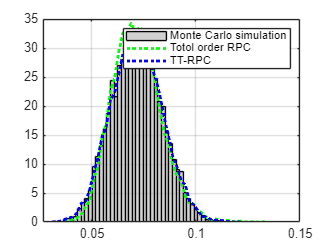



f_k = 100;

f = figure(2);
Hmc = histogram(abs(y_test(:,f_k)) ,50,'Normalization','pdf', 'DisplayStyle','bar', 'FaceColor',[0.7 0.7 0.7]);
hold on
grid on
[N_k,edges] = histcounts(abs(y_predict(:,f_k)), 'Normalization', 'pdf');
plot(edges(1:end-1)+(edges(2)-edges(1))/2,N_k,'g:','LineWidth',2)
[N_k,edges] = histcounts(abs(y_predict2(:,f_k)), 'Normalization', 'pdf');
plot(edges(1:end-1)+(edges(2)-edges(1))/2,N_k,'b:','LineWidth',2)
legend('Monte Carlo simulation','Totol order RPC', 'TT-RPC')